clc
clear all
close all
N_DOFS = 7;
link_length=3; %for a manipulator where all links are the same length
link_offset=5;
link_inertia=10;
link_mass=1;
% Define the DH parameters

dh.theta=zeros(1,N_DOFS);
dh.alpha = zeros(1,N_DOFS);
dh.alpha(2:3)= pi/2;

dh.d = zeros(1,N_DOFS); dh.d(3)=link_offset;
dh.a = link_length*ones(1,N_DOFS); 

% Define rigid body parameters: inertia, mass, and center of mass

rb.I =  repmat(link_inertia*eye(3), 1, 1, N_DOFS);

rb.m = link_mass*ones(1,N_DOFS);

% In standard DH, COM is measured respect to its end-effector (using local
% frame). When COM is [0 0 0]', it means the COM is located exactly at the
% end-effector. Therefore, COM usually has negative values, which means the
% COM is behind the end-effector

% this is super idealized
% for uniform density, cylindrically symmetrical links
rb.r=-0.5*[dh.a;zeros(1,N_DOFS);dh.d]; 

% -------------------------------------------------------------------------
% Arbitrary trajectory as the inputs: joint position, velocity, and 
% acceleration
ts = 0.1;
time_span = 0:ts:1;

qcC= pi/3*sin(2*pi*time_span)';
qc=repmat(qcC,[1,N_DOFS]);

qcdot = gradient(qc', ts)';
qcddot = gradient(qcdot', ts)';

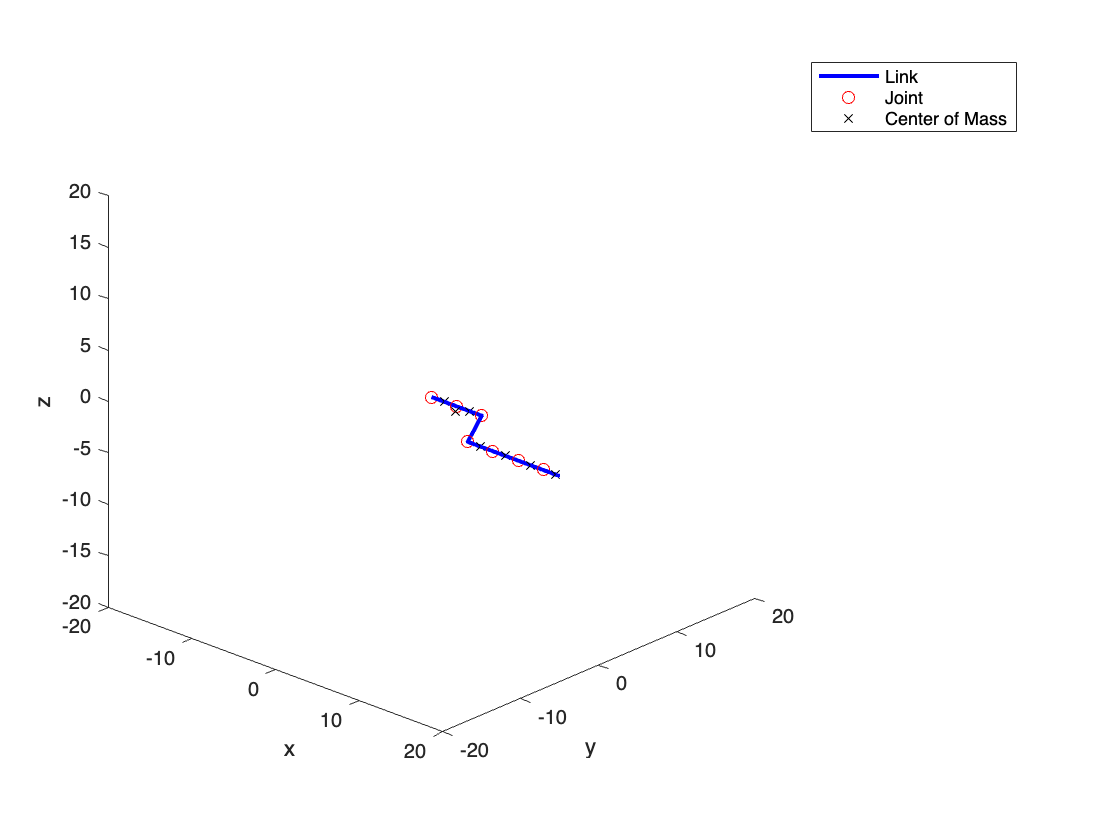


% Kinematic simulation, optional, for visualization purpose!   
% End-effector position, from the base which is located at [0 0 0]'
max_axis=20;
figure('color',[1 1 1]); set(gca, 'XLim', [-max_axis max_axis], 'YLim', [-max_axis max_axis], 'ZLim', [-max_axis max_axis]); view(43,24); hold on;
h1 = plot3(0,0,0, 'b', 'linewidth',2);   % The link
h2 = plot3(0,0,0, 'or');  % The joint/end-effector
h3 = plot3(0,0,0, 'xk');  % The center of mass
xlabel('x')
ylabel('y')
zlabel('z')
legend('Link', 'Joint', 'Center of Mass')
EE = zeros(3, N_DOFS+1);
COM = zeros(3, N_DOFS);    
for k = 1 : length(time_span)  
    for i = 1 : 1 : N_DOFS
        T = simplified_transformation(i, dh, qc(k,:));
        EE(:,i+1) = T(1:3,4);
        COM(:,i) = EE(:,i+1) + T(1:3,1:3) * rb.r(:,i);
    end
    
    % Draw the robot
    set(h1, 'XData', EE(1, :), 'YData', EE(2, :),'ZData', EE(3, :));
    set(h2, 'XData', EE(1, :), 'YData', EE(2, :),'ZData', EE(3, :));
    set(h3, 'XData', COM(1, :), 'YData', COM(2, :),'ZData', COM(3, :));
    drawnow;
end


function  T = simplified_transformation(n, dh, qc)
    % input dh as struct
    % Transformation from base joint to another joint
    % Removed prismatic joints, angle offset
    T = eye(4);
    
    for i = 1 : n
        dh.theta(i) = qc(i);
        
        ct = cos(dh.theta(i));
        st = sin(dh.theta(i));
        ca = cos(dh.alpha(i));
        sa = sin(dh.alpha(i));
        
        T = T * [ ct    -st*ca   st*sa     dh.a(i)*ct ; ...
                  st    ct*ca    -ct*sa    dh.a(i)*st ; ...
                  0     sa       ca        dh.d(i)    ; ...
                  0     0        0         1          ];
    end
end